Use for **reseting the program**

clear;

**Setting the constant **(Fuel Properties)

fuel = ["B7";"B100"];
CalorificValue = [42.72;37.41];
fuelprop = table(fuel, CalorificValue);
Case = ["B7" "B7 with DPF" "B100" "B100 with DPF"];

**Import file**

RawData = importfile("/Users/penquin/Library/CloudStorage/OneDrive-KMITL/Project/Raw_Data.xlsx", "Fuel Consumption", [2, Inf]);
RawData.BrakePower = pi() * RawData.RPM .* RawData.Torque / (30 * 1000);
RawData.Properties.VariableNames(4:2:6) = ["B7withDPF" "B100withDPF"];

**Analysis of Fuel**

-> using by typing "Condition.(fuel)" to show Fuel table

Condition = FuelAnalysation(RawData, fuelprop);

**Table of Properties**

-> using by typing "Properties.(properties)" to show Properties table

Properties = PropAnalysation(Condition);

**Bar plot of Fuel Consumtion**

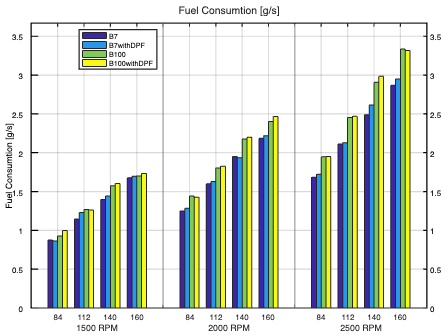

tile = ft_bar(Properties.FuelConsum, "Fuel Consumtion [g/s]");

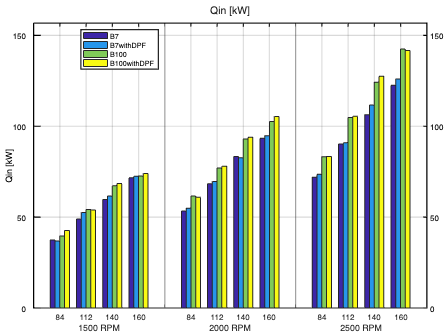

tile2 = ft_bar(Properties.Qin, "Qin [kW]");

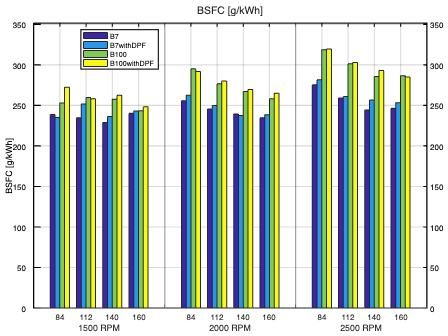

tile3 = ft_bar(Properties.BSFC, "BSFC [g/kWh]");

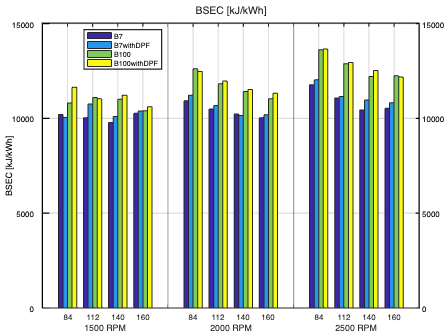

tile4 = ft_bar(Properties.BSEC, "BSEC [kJ/kWh]");

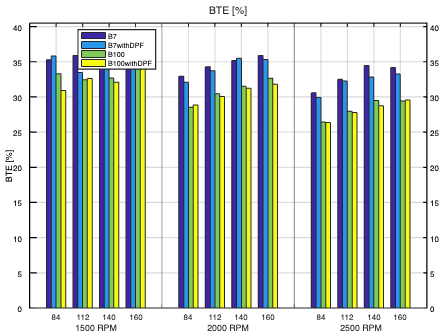

tile5 = ft_bar(Properties.BTE, "BTE [%]");